# Human Activity Classification based on Smartphone Sensor Signals

## Introduction

This example describes an analysis approach on** accelerometer signals captured with a smartphone**. The smartphone is worn by a subject during **6 different types of physical activity**. The goal of the analysis is to build an algorithm that automatically identifies the activity type given the sensor measurements. 

The example uses data from a recorded dataset, courtesy of: Davide Anguita, Alessandro Ghio, Luca Oneto, Xavier Parra and Jorge L. Reyes-Ortiz. Human Activity Recognition on Smartphones using a Multiclass Hardware-Friendly Support Vector Machine. International Workshop of Ambient Assisted Living (IWAAL 2012). Vitoria-Gasteiz, Spain. Dec 2012

The original dataset is available from [http://archive.ics.uci.edu/ml/datasets/Human+Activity+Recognition+Using+Smartphones](http://archive.ics.uci.edu/ml/datasets/Human+Activity+Recognition+Using+Smartphones)

clear;

## Objective of the example

Let's take a look at what our final result may look like. This will give us a better feel for what we are trying to achieve. For the time being you do not need to understand how this is realized

runClassifierOnBufferedData

## Open "recording" for a single subject (e.g. #1)

Let's look at the data. Given the data:

- We would like to be able to tell the difference between the different activities, just based on the content of the signal. 

- Note in this case the coloring is based on existing knowledge (actid)

- Labeled data can be used to "train" a classification algorithm so it can it later predict the class of new (unlabeled) data. 

% Use a custom function to retrieve a single acceleration component for a
% particular subject.
[acc, actid, actlabels, t, fs] = getRawAcceleration('SubjectID',1,...
    'Component','z');

% Visualize the same signal using a custom plotting function, which also
% uses the information in actid
plotAccelerationColouredByActivity(t, acc, actid, {'Vertical acceleration'})

## First type of characterization - amplitude only

Looking only at the raw values irrespective or their position is time can provide a first set of clues

## First example - Using a mean measure

This can easily help separate e.g. Walking from Laying

figure
plotCompareHistForActivities(acc, actid,'Walking', 'Laying')

## Second example - Using an RMS or standard deviation measure

This can help separate things like e.g. Walking and Standing

plotCompareHistForActivities(acc, actid,'Walking', 'Standing')

## What next? Amplitude-only methods are often not enough

For example it would be very hard to distinguish between simply Walking and WalkingUpstairs (very similar statistical moments)

An initial conclusion is that simple **statistical analysis is often not sufficient**. For signals one should also consider methods that measure signal variations over time

plotCompareHistForActivities(acc, actid,'Walking', 'WalkingUpstairs')

## Time-domain analysis - preliminary considerations

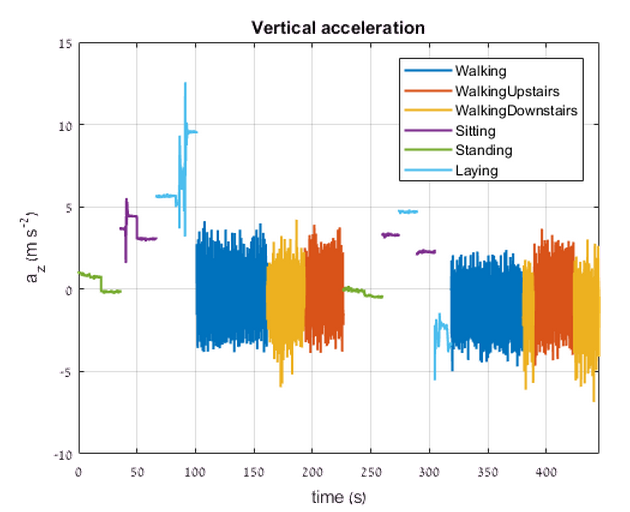

There are two main different types of causes behind our signals: 

- One to do with **"fast" variations** over time, due to body dynamics (physical movements of the subject)

- The other, responsible for **"slow" variations** over time, due to the position of the body with respect to the vertical gravitational field

As we focus on classifying the physical activities, we should focus time-domain analysis on the effects of body movements. These are responsible for the most "rapid" (or frequent) variations in our signal.

In this specific case a simple average over a period of time would easily estimate the gravitational component, which could be then subtracted from the relevant samples to obtain the signal due to the physical movements.

For the sake of generality here we introduce an approach based on digital filters, which is much more general and can be reused in more challenging situations.

## Digital filtering workflow

To isolate the rapid signal variations from the slower ones using digital filtering:

- Design a **high-pass filter** (e.g. using the Filter Designer Tool in MATLAB)

- Apply the filter to the original signal

filterDesigner; % load saved HPF.fda

## Filter out gravitational acceleration

As well as interactively, filters can be designed programmatically. In this case the **function hpfilter was generated automatically** from the Filter Designer Tool , but it could have just as well been created manually

% Design filter
fhp = hpfilter; % was generated automatically

% "Decouple" acceleration due to body dynamics from gravity
af = filter(fhp,acc);

% Compare the filtered signal with the original one
plotAccelerationColouredByActivity(t, [acc, af], actid,...
    {'Original','High-pass filtered'})

## Focus on a single activity first: select first portion of Walking signal

Only **select samples** for which the activity was Walking and for which the time was less than 250 seconds.

% Activity id for Walking is 1
walking = 1;
sel = (t < 250) & (actid == walking);

% Select only desired array segments for time vector and acceleration signal
tw = t(sel);
af_walk = af(sel);

% Plot walking-only signal segment. Use interactive plot tools to zoom in
% and explore the signal. Note the quasi-periodic behavior.
figure
plotAccelerationColouredByActivity(tw, af_walk, [],'Walking')

## Plot Power Spetral Density

Use Welch method with its default options, using known sample frequency

% When called without output arguments, the function pwelch plots the PSD
figure
pwelch(af_walk,[],[],[],fs)

## Validate potential of PSD to differentiate between different activities

E.g. are position and height in the two respsctive sets of peaks different for different activities?

plotPSDActivityComparisonForSubject(1, 'Walking', 'WalkingUpstairs')

## Automate peak identification

The function **findpeaks** in Signal Processing Toolbox can be used to identify amplitude and location of spectral peaks

Refine peak finding by adding  specific requirements to the findpeaks function.

% PSD with numerical output
[p,f] = pwelch(af_walk,[],[],[],fs);

% Find max 8 peaks, at least 0.25Hz apart from each other and with a given
% prominence value

fmindist = 0.25;                    % Minimum distance in Hz
N = 2*(length(f)-1);                % Number of FFT points
minpkdist = floor(fmindist/(fs/N)); % Minimum number of frequency bins

[pks,locs] = findpeaks(p,'npeaks',8,'minpeakdistance',minpkdist,...
    'minpeakprominence', 0.15);

% Plot PSD and overlay peaks
plot(f,db(p),'.-')
grid on
hold on
plot(f(locs),db(pks),'rs')
xlim([0 20])
addActivityLegend(1)
title('Power Spectral Density with Peaks Estimates')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

## Feature summary

After exploring interactively a few different techniques to extract **descriptive features** from this type of signals, we can collect all the analysis methods identified into a single function.

The function **extracts a fixed number of features** for each signal buffer provided as input.

edit extractSignalFeatures % see features

sloc counts number source lines of code -  from MATLAB Central: [https://www.mathworks.com/matlabcentral/fileexchange/3900-sloc](https://www.mathworks.com/matlabcentral/fileexchange/3900-sloc)

sloc('extractSignalFeatures.m') % number of source lines

## Prepare data to train classifier

To train a classifier:

- Re-organise the acceleration signals into **shorter buffers of fixed length L**, each labeled with a single activity ID

- **Extract a vector of features** for each Lx3 signal buffer [ax, ay, az] 

- Provide an **activity ID (a "label") for each feature vector**, used to train or test the classifier

To re-compute all features use the function extractAllFeatures, which

- Reads the buffered signals from BufferedAccelerations.mat

- Computes a feature vector for each buffer using featuresFromBuffer

- Saves all feature vectors into the file BufferFeatures.mat

Computing the features is a fairly efficient process, but it takes a while in this case because of the high number of signal vectors available. extractAllFeatures can distribute the computations to a pool of workers if Parallel Computing Toolbox is installed

If you have Parallel Computing Toolbox and a valid parallel pool available, extractAllFeatures will run in parallel using **parfor**.

edit extractAllFeatures % see parfor

## Use pre-computed feature dataset

A pre-computed set of feature vectors for all available signal buffers is available in the file BufferFeatures.mat

Extraction of 66 features from 10,299 segments took ~2 minutes using 4 workers pool (in my computer)

% Clear nonrelevant variables
clear

% Load:
% * Pre-computed feature vectors (feat) and labels (actid, subid)
% * Feature names (featlabels)
% * Feature normalization parameters (fmean, fstd)
load('BufferFeatures.mat')

% Create a table (useful to quicly train)
featT = array2table(feat,'VariableNames',featlabels);  % predictors
actidT = table(categorical(actid,1:6,actnames),'VariableNames',{'ActivityID'}); % response
featuresTable = [featT, actidT]; % horzcat

## Identify a suitable classifier interactively

The Statistics and Machine Learning Toolbox provides a long list of algorithms for classifiaction.

The accelerate choosing the right classifier use the Classification Learner App

classificationLearner

## Train a  classifier

Use a MATLAB function that was **auto-generated by the Classification Learner App **to train a classifiar based on the dataset. The returned arguments include information of how the dataset was partition during the training phase - so the remaining samples of the dataset can be used for testing the accuracy of the classifier. 

Bootstrap aggregating(bagging) is an ensemble algorithm leads to "improvements for unstable procedures". Bagging is a special case of the model averaging approach, and it improves stability and accuracy, reduces variance, helps to avoid overfitting

% Train the classifier
[trainedBaggedClassifier, accuracy, cvp] = trainBaggedTreesEnsClassifier(featuresTable);
%load('trainedBaggedClassifier.mat')

% Test results programmatically
% Use the part of the dataset that was not used for trainig
featTest = featT(cvp.test,:);
actidTest = actidT(cvp.test,:);
predictedActid = trainedBaggedClassifier.predictFcn(featTest);
% Visualize the prediction results as a confusion matrix
% confusionmatrix = confusionmat(actidTest.ActivityID,predictedActid); heatmap(confusionmatrix)
plotconfusion(dummyvar(double(actidTest.ActivityID))',dummyvar(double(predictedActid))')


## Save Model

Use saveCompactModel function to save compact version of the model, which will be used for C code conversion

load('trainedBaggedClassifierNum.mat') % covert Categorical for code generation
saveCompactModel(trainedBaggedClassifier.ClassificationEnsemble,'trainedModel');

## Run Classifier on buffered data

We have now completed all the algorithmic steps necessary to implement the classification system presented at the very beginning of this example.

runClassifierOnBufferedData

## Generate code from predictActivityFromSignalBuffer

MATLAB Coder can be used to automatically generate source C/C++, which can be also deployed to an embedded architecture

edit predictActivityFromSignalBuffer

load WS 
coder % use function call "predictActivityFromSignalBuffer(at, fs, fmean, fstd)" in coder

Additional Information - Connect to Smartphone using MATLAB Connector:

[https://www.mathworks.com/help/matlabmobile/connect-to-your-computer.html](https://www.mathworks.com/help/matlabmobile/connect-to-your-computer.html)